% define mean and sd
mu1 = [0.4; 0.6]

mu1 =     0.4000
    0.6000


sd1 = [0.9; 0.7]

sd1 =     0.9000
    0.7000


mu2 = [2.5; 3.0]

mu2 =     2.5000
    3.0000


sd2 = [0.9; 0.7]

sd2 =     0.9000
    0.7000



% Training
% Class 1 - 1000
X_train_c1 = randn(2, 1000) .* sd1 + mu1;
Y_train_c1 = zeros(1, 1000);

% Class 2 - 800
X_train_c2 = randn(2, 800) .* sd2 + mu2;
Y_train_c2 = ones(1, 800);

X_train = [X_train_c1, X_train_c2];
Y_train = [Y_train_c1, Y_train_c2];

% Testing
% Class 1 - 500
X_test_c1 = randn(2, 500) .* sd1 + mu1;
Y_test_c1 = zeros(1, 500);

% Class 2 - 400
X_test_c2 = randn(2, 400) .* sd2 + mu2;
Y_test_c2 = ones(1, 400);

X_test = [X_test_c1, X_test_c2];
Y_test = [Y_test_c1, Y_test_c2];

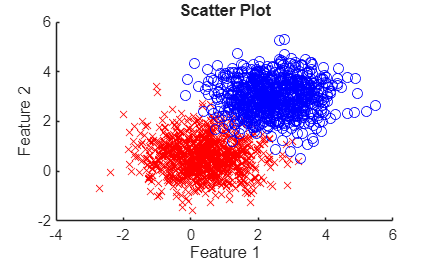

figure
scatter(X_train_c1(1,:),X_train_c1(2,:), 'red', 'x');
hold on;
scatter(X_train_c2(1,:),X_train_c2(2,:), 'blue', 'o');
hold off;
title('Scatter Plot');
xlabel('Feature 1');
ylabel('Feature 2');